# 通过 PSO 算法进行 PID 参数整定

 
clear;clc

## 1.系统参数设定

 
m = 1;
c = 0;
k = 1;
dt = 0.01;
T = 10;
v0 = 1; % 初速度

% PSO 参数
swarm_size = 32;  % 种群规模
max_iter = 200; % 最大迭代次数
v_mm = [-1 1]; %速度約束
c1 = 1.3; % 局部学习因子
c2 = 1.7; % 全局学习因子
w_mm = [0.1 0.9]; % 时变惯性权重約束
%tolerance = 1e-21; % 容许误差


## 2.基于状态空间搭建系统

 
A = [0 1;
    -k/m -c/m];
B = [0;1/m];
C = [1 0];
D = 0;
sys = ss(A,B,C,D);

R = Function_PSO_PID_Rewardfx(8.9797,2.3541,5.3070,sys,dt,T);

## 3.基于PSO算法对PID进行参数整定

% 创建优化变量
Kp_hat = optimvar("Kp_hat","LowerBound",0,"UpperBound",50);
Ki_hat = optimvar("Ki_hat","LowerBound",-50,"UpperBound",50);
Kd_hat = optimvar("Kd_hat","LowerBound",0,"UpperBound",50);

% 设置求解器的初始起点
initialPoint.Kp_hat = repmat(7,size(Kp_hat));
initialPoint.Ki_hat = repmat(7,size(Ki_hat));
initialPoint.Kd_hat = repmat(7,size(Kd_hat));

% 创建问题(最大化奖励函数)
problem = optimproblem("ObjectiveSense","Maximize");

% 定义问题目标
problem.Objective = fcn2optimexpr(@Function_PSO_PID_Rewardfx,Kp_hat,Ki_hat,Kd_hat,sys,...
    dt,T);

% 设置非默认求解器选项
options = optimoptions("particleswarm","Display","iter","InertiaRange",w_mm,"MaxIterations",max_iter,"SelfAdjustmentWeight",c1,...
    "SocialAdjustmentWeight",c2,"SwarmSize",swarm_size,"PlotFcn","pswplotbestf");

% 显示问题信息
show(problem);


  OptimizationProblem : 

	Solve for:
       Kd_hat, Ki_hat, Kp_hat

	maximize :
       Function_PSO_PID_Rewardfx(Kp_hat, Ki_hat, Kd_hat, extraParams{1}, 0.01, 10)

       extraParams


	variable bounds:
       0 <= Kd_hat <= 50

       -50 <= Ki_hat <= 50

       0 <= Kp_hat <= 50




% 求解问题
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","particleswarm","Options",options);

将使用 particleswarm 求解问题。

                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              32          -61.61      -7.535e+05        0
    1              64          -61.61      -3.194e+29        0
    2              96          -61.61      -2.219e+15        1
    3             128          -61.61      -9.218e+15        2
    4             160          -61.61      -1.612e+15        3
    5             192          -61.61      -4.292e+18        4
    6             224          -58.28      -7.257e+22        0
    7             256          -58.28      -1.099e+09        1
    8             288          -58.28      -3.552e+19        2
    9             320          -58.28       -1.47e+11        3
   10             352          -56.86          -297.9        0
   11             384          -56.86      -2.754e+04        1
   12             416          -56.13          -342.7        0
   13             448   

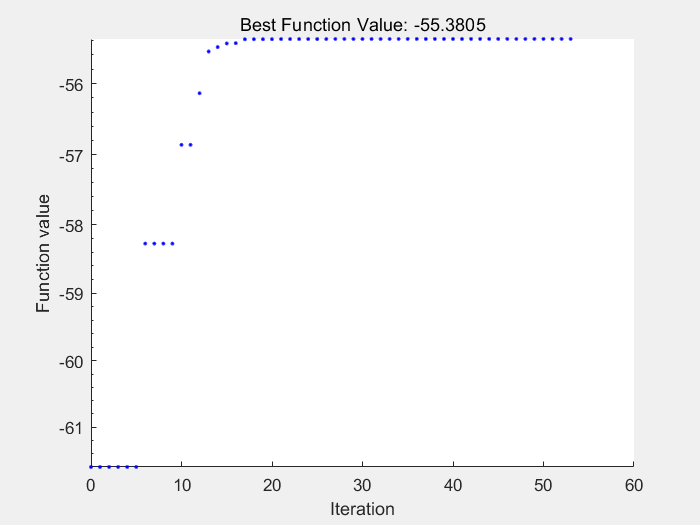

set(gca, 'YScale', 'log'); % 将当前图示的坐标转化为对数坐标

## 为什么优化的结果ki会趋于0


% 显示结果
solution

solution = 包含以下字段的 struct :
    Kd_hat: 5.0831
    Ki_hat: 0.0014
    Kp_hat: 8.5253


reasonSolverStopped

reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue

objectiveValue = -55.3805


% 清除变量
clearvars Kp_hat Ki_hat Kd_hat initialPoint options reasonSolverStopped objectiveValue